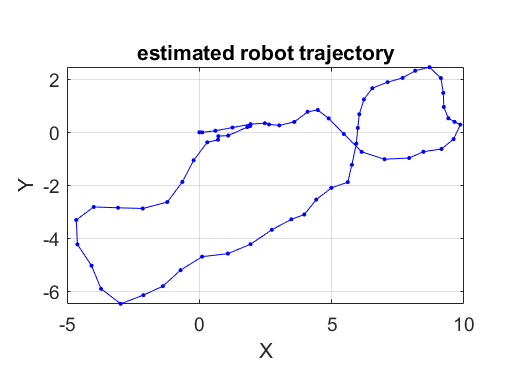

%loaded the LiDAR scans
data = load('offlineSlamData.mat');
scans = data.scans;


%Robot Trajectory Estimation
maxLidarRange =  8;
mapResolution = 10;
pGraph = poseGraph;
infoMat = [1 0 0 1 0 1];
prevScan = scans{1};
for i = 2:numel(scans)
    currScan = scans{i};
    [relPose,stats] = matchScansGrid(currScan,prevScan,'MaxRange',maxLidarRange,'Resolution',mapResolution);
    relPoseRefined = matchScans(currScan,prevScan,'InitialPose',relPose);
    pGraph.addRelativePose(relPoseRefined,infoMat);
    ax = show(pGraph,'IDs','off');
    title(ax,'estimated robot trajectory')
    drawnow
    prevScan = currScan;
end

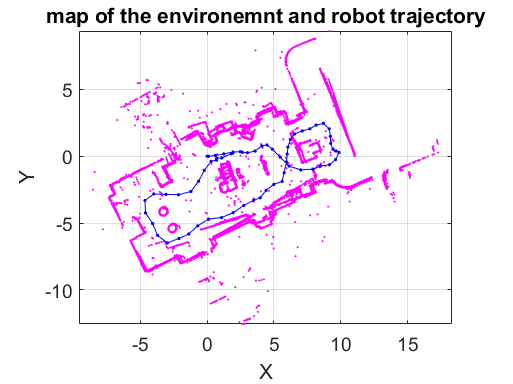



%Optimisation to the above
hFigMap = figure;
axMap = axes('parent',hFigMap);
helperShow(scans,pGraph,maxLidarRange,axMap);
title(axMap,'map of the environemnt and robot trajectory')

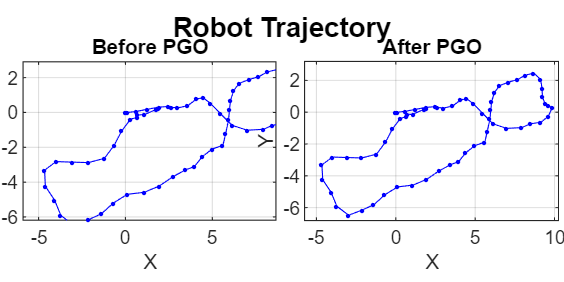



%Drift Correction
 %(by loop closure)
loopClosureThreshold = 110;
loopClosureSearchRadius = 2;


%Trajectory Optimisation
% if ~isempty(loopClosureEdgeIds)
%     for k = 1:size(loopClosureEdgeIds,1)
%         pGraph.addRelativePose(loopClosurePoses(k,:),infoMat, ...
%             loopClosureEdgeIds(k,1),loopClosureEdgeIds(k,2));
%     end
% end
 updatedPGraph = optimizePoseGraph(pGraph);


%Visualiation
hFigTraj = figure('Position',[0 0 900 450]);
%before optimisation
axPGraph = subplot(1,2,1,'Parent',hFigTraj);
axPGraph.Position = [0.04 0.1 0.45 0.8];
show(pGraph,'IDs','off','Parent',axPGraph);
title(axPGraph,'Before PGO')

% after optimisation
axUpdatedPGraph = subplot(1,2,2,'Parent',hFigTraj);
axUpdatedPGraph.Position = [0.54 0.1 0.45 0.8];
show(updatedPGraph,'IDs','off','Parent',axUpdatedPGraph);
title(axUpdatedPGraph,'After PGO')
axis([axPGraph axUpdatedPGraph],[-6 10 -7 3])
sgtitle('Robot Trajectory','FontWeight','bold')



% some helper functions


function helperShow(scans,pGraph,maxRange,ax)
    hold(ax,'on')
    for i = 1:numel(scans)
        sc = transformScan(scans{i}.removeInvalidData('RangeLimits',[0.02 maxRange]), ...
            pGraph.nodes(i));
        scPoints = sc.Cartesian;
        plot(ax,scPoints(:,1),scPoints(:,2),'.','MarkerSize',3,'color','m')
    end
    nds = pGraph.nodes;
    plot(ax,nds(:,1),nds(:,2),'.-','MarkerSize',5,'color','b')
    hold(ax,'off')
    axis(ax,'equal')
    box(ax,'on')
    grid(ax,'on')
    xlabel('X')
    ylabel('Y')
end

% THE END 